# EXample vocalization with PAF measurements

BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
LocalDataDir = '/Users/elie/Documents/DeafBats/Data';

Data = load(fullfile(BaseDataDir,'20200312', 'audiologgers','200312_1026_VocExtractData1_200.mat'));

Select a particular call

BioSoundCall = Data.BioSoundCalls(26,:);

Plot the microphone oscillogram of the second element

figure()
plot(BioSoundCall{1,1}.sound(BioSoundCall{1,1}.OnOffSets_elmts(2,1) : BioSoundCall{1,1}.OnOffSets_elmts(2,2)), '-k', 'LineWidth',2);
set(gca, 'XTick',[])
set(gca, 'YTick',[], 'YColor', 'w')
set(gca, 'XAxisLocation', 'origin')
box off

Plot the microphone spectrum of the second element with values obtaines for spectral features

figure()
plot(BioSoundCall{1,1}.psdf{2}./10^3, BioSoundCall{1,1}.psd{2}, 'k-', 'LineWidth',2)
hold on
V1=vline(BioSoundCall{1,1}.MeanQ1t(2)/10^3, '--r');
V1.LineWidth=2;
text(BioSoundCall{1,1}.MeanQ1t(2)/10^3, 0.085, 'Q1', 'Color', 'r', 'FontSize',16)
hold on
V2=vline(BioSoundCall{1,1}.MeanQ2t(2)/10^3, '--b');
V2.LineWidth=2;
text(BioSoundCall{1,1}.MeanQ2t(2)/10^3, 0.085, 'Q2', 'Color', 'b', 'FontSize',16)
hold on
V3=vline(BioSoundCall{1,1}.MeanQ3t(2)/10^3, '--g');
V3.LineWidth=2;
V3.Color = [0.5 0 0.5];
text(BioSoundCall{1,1}.MeanQ3t(2)/10^3, 0.085, 'Q3', 'Color', [0.5 0 0.5], 'FontSize',16)
xlabel('Frequency (kHz)', 'FontSize',16)
text(22, 0.08, sprintf('Spectral mean = %.1f kHz', BioSoundCall{1,1}.meanspect(2)/10^3), 'FontSize',16)
text(22, 0.07, sprintf('Spectral std = %.1f kHz', BioSoundCall{1,1}.stdspect(2)/10^3), 'FontSize',16)
text(22, 0.06, sprintf('Spectral kurtosis = %.2f', BioSoundCall{1,1}.kurtosisspect(2)), 'FontSize',16)
text(22, 0.05, sprintf('Spectral skewness = %.2f', BioSoundCall{1,1}.skewspect(2)), 'FontSize',16)
text(22, 0.04, sprintf('Spectral entropy = %.2f', BioSoundCall{1,1}.entropyspect(2)), 'FontSize',16)
text(22, 0.03, sprintf('First Quartile (Q1) = %.1f kHz', BioSoundCall{1,1}.MeanQ1t(2)/10^3), 'FontSize',16)
text(22, 0.02, sprintf('Second Quartile (Q2) = %.1f kHz', BioSoundCall{1,1}.MeanQ2t(2)/10^3), 'FontSize',16)
text(22, 0.01, sprintf('Third Quartile (Q3) = %.1f kHz', BioSoundCall{1,1}.MeanQ3t(2)/10^3), 'FontSize',16)
ylim([0 0.1])
set(gca, 'YTick',[0 0.1])
ylabel('Power (linear)', 'FontSize',16)
hold off
box off

Plot the piezo oscillogram

figure()
plot(BioSoundCall{1,2}.sound(BioSoundCall{1,2}.OnOffSets_elmts(2,1) : BioSoundCall{1,2}.OnOffSets_elmts(2,2)), '-k', 'LineWidth',2);
set(gca, 'XTick',[], 'XAxisLocation', 'origin')
set(gca, 'YTick',[], 'YColor', 'w')
box off

Plot the piezo spectrum with values obtained for the spectral features

figure()
plot(BioSoundCall{1,2}.psdf{2}./10^3, BioSoundCall{1,2}.psd{2}, 'k-', 'LineWidth',2)
hold on
V1=vline(BioSoundCall{1,2}.MeanQ1t(2)/10^3, '--r');
V1.LineWidth=2;
text(BioSoundCall{1,2}.MeanQ1t(2)/10^3, 0.047, 'Q1', 'Color', 'r', 'FontSize',16)
hold on
V2=vline(BioSoundCall{1,2}.MeanQ2t(2)/10^3, '--b');
V2.LineWidth=2;
text(BioSoundCall{1,2}.MeanQ2t(2)/10^3, 0.047, 'Q2', 'Color', 'b', 'FontSize',16)
hold on
V3=vline(BioSoundCall{1,2}.MeanQ3t(2)/10^3, '--g');
V3.LineWidth=2;
V3.Color = [0.5 0 0.5];
text(BioSoundCall{1,2}.MeanQ3t(2)/10^3, 0.047, 'Q3', 'Color', [0.5 0 0.5], 'FontSize',16)
xlabel('Frequency (kHz)', 'FontSize',16)
text(6, 0.045, sprintf('Spectral mean = %.1f kHz', BioSoundCall{1,2}.meanspect(2)/10^3), 'FontSize',16)
text(6, 0.04, sprintf('Spectral std = %.1f kHz', BioSoundCall{1,2}.stdspect(2)/10^3), 'FontSize',16)
text(6, 0.035, sprintf('Spectral kurtosis = %.2f', BioSoundCall{1,2}.kurtosisspect(2)), 'FontSize',16)
text(6, 0.03, sprintf('Spectral skewness = %.2f', BioSoundCall{1,2}.skewspect(2)), 'FontSize',16)
text(6, 0.025, sprintf('Spectral entropy = %.2f', BioSoundCall{1,2}.entropyspect(2)), 'FontSize',16)
text(6, 0.02, sprintf('First Quartile (Q1) = %.1f kHz', BioSoundCall{1,2}.MeanQ1t(2)/10^3), 'FontSize',16)
text(6, 0.015, sprintf('Second Quartile (Q2) = %.1f kHz', BioSoundCall{1,2}.MeanQ2t(2)/10^3), 'FontSize',16)
text(6, 0.01, sprintf('Third Quartile (Q3) = %.1f kHz', BioSoundCall{1,2}.MeanQ3t(2)/10^3), 'FontSize',16)
ylim([0 0.05])
set(gca, 'YTick',[0 0.05])
ylabel('Power (linear)', 'FontSize',16)
hold off
box off

Plot the piezo amplitude envelope with values for time features

figure()
plot(BioSoundCall{1,2}.sound(BioSoundCall{1,2}.OnOffSets_elmts(2,1) : BioSoundCall{1,2}.OnOffSets_elmts(2,2)), '-k', 'LineWidth',2);
set(gca, 'XTick',[], 'XAxisLocation', 'origin', 'XColor', 'w', 'YColor', 'w')
set(gca, 'YTick',[])
hold on
plot(BioSoundCall{1,2}.ampt_elmts{2}.*50000, BioSoundCall{1,2}.amp_elmts{2}*3, 'r-', 'LineWidth',2)
XLIM = get(gca, 'XLim');
xlim([0 3*XLIM(2)])
text(19000, 0.7, sprintf('Temporal mean = %.1f ms', BioSoundCall{1,2}.meantime(2)), 'FontSize',16)
text(19000, 0.55, sprintf('Temporal std = %.1f ms', BioSoundCall{1,2}.stdtime(2)), 'FontSize',16)
text(19000, 0.4, sprintf('Temporal kurtosis = %.2f', BioSoundCall{1,2}.kurtosistime(2)), 'FontSize',16)
text(19000, 0.25, sprintf('Temporal skewness = %.2f', BioSoundCall{1,2}.skewtime(2)), 'FontSize',16)
text(19000, 0.1, sprintf('Temporal entropy = %.2f', BioSoundCall{1,2}.entropytime(2)), 'FontSize',16)
text(19000, -0.05, sprintf('RMS = %.2f', BioSoundCall{1,2}.rms), 'FontSize',16)
text(19000, -0.2, sprintf('Duration = %.d ms', diff(BioSoundCall{1,2}.OnOffSets_elmts)/50), 'FontSize',16)
SoundAmp = BioSoundCall{1,2}.amp_elmts{2};
[P,F] = pspectrum(SoundAmp,1000);
[PKS,LOCS]=findpeaks(P);
text(19000, -0.35, sprintf('Amplitude period frequency = %.2f Hz', F(LOCS(PKS == max(PKS)))), 'FontSize',16)
text(19000, -0.5, sprintf('Amplitude period power = %.2f', max(PKS)/mean(SoundAmp.^2)), 'FontSize',16)
hold off
box off

Plot the piezo spectrogram with values for saliency, F0...

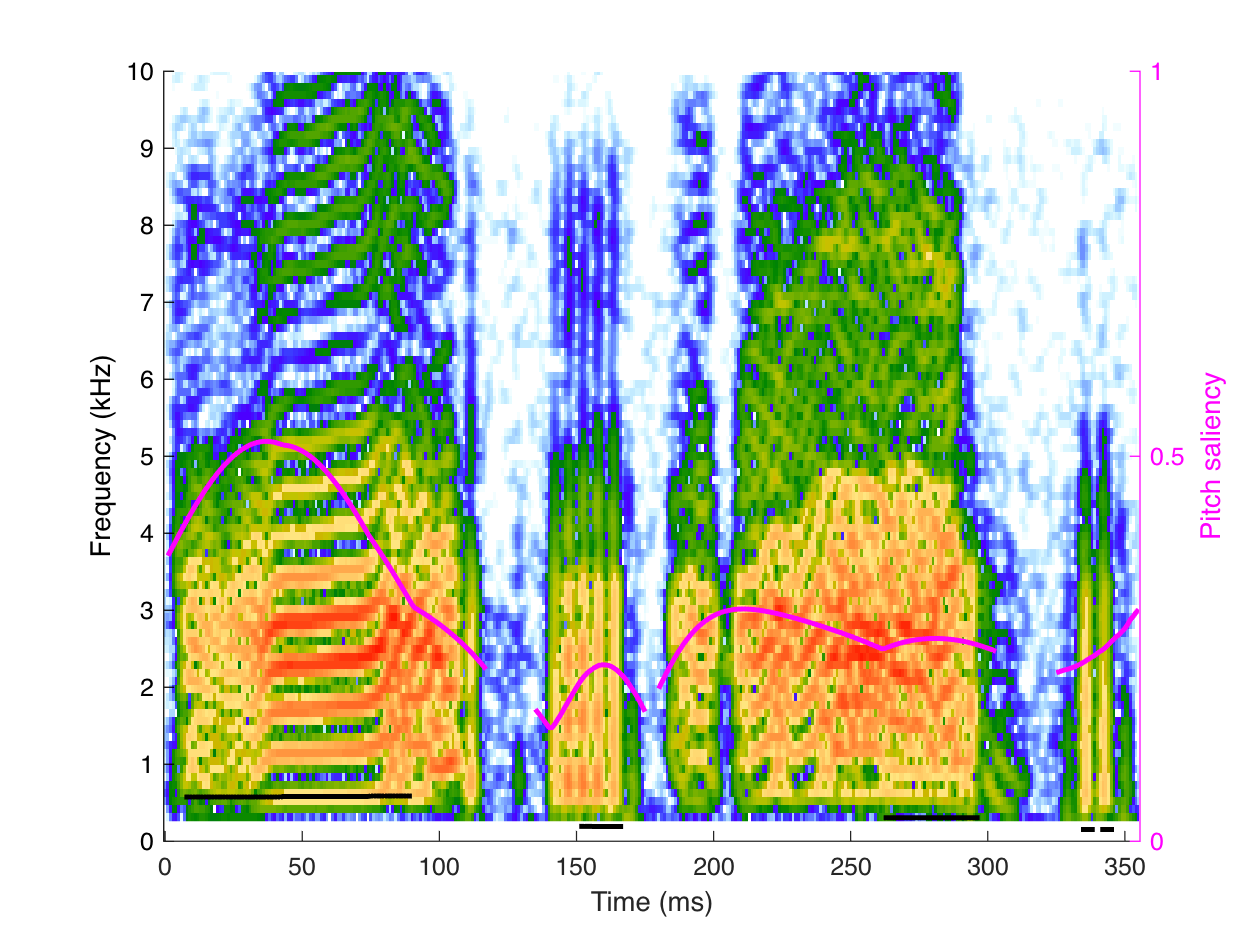

DBNOISE=60;
F=figure();
logB = BioSoundCall{1,2}.spectro_elmts{2};
maxB = max(max(logB));
minB = maxB-DBNOISE;
To = 1:size(BioSoundCall{1,2}.spectro_elmts{2},1);
IM=imagesc(BioSoundCall{1,2}.to_elmts{2}*10^3,BioSoundCall{1,2}.fo_elmts{2}/10^3,logB);          % to is in seconds
axis xy;
caxis('manual');
caxis([minB maxB]);
cmap = spec_cmap();
colormap(IM.Parent, cmap);
v_axis = axis;
v_axis(3)=0;
v_axis(4)=10;
axis(v_axis);
ylabel('Frequency (kHz)')
xlabel('Time (ms)')
box off
hold on
plot(BioSoundCall{1,2}.f0(end-BioSoundCall{1,2}.to_elmts{2}(end)*10^3:end)/10^3, 'k-',  'LineWidth',2)
yyaxis right
plot(BioSoundCall{1,2}.sal(end-BioSoundCall{1,2}.to_elmts{2}(end)*10^3:end), 'm-', 'LineWidth',2)
F.Children.YColor = 'm';
ylabel('Pitch saliency')
ylim([0 1])
yticks(0:0.5:1)

fprintf('Pitch Saliency = %.1f', BioSoundCall{1,2}.MeanSal(2))

Pitch Saliency = 0.3

fprintf('Fundamental = %.1f Hz', BioSoundCall{1,2}.MeanF0(2))

Fundamental = 434.8 Hz

OnOffSetsTime = ceil(BioSoundCall{1,2}.OnOffSets_elmts(2,:)./BioSoundCall{1,2}.samprate.*1000);
Fund = BioSoundCall{1,2}.f0(OnOffSetsTime(1):min(OnOffSetsTime(2), length(BioSoundCall{1,2}.f0)));
CVFund = std(Fund, 'omitnan')/mean(Fund,'omitnan');
fprintf('CV Fundamental = %.3f Hz', CVFund)

CV Fundamental = 0.394 Hz

Plot the microphone MPS

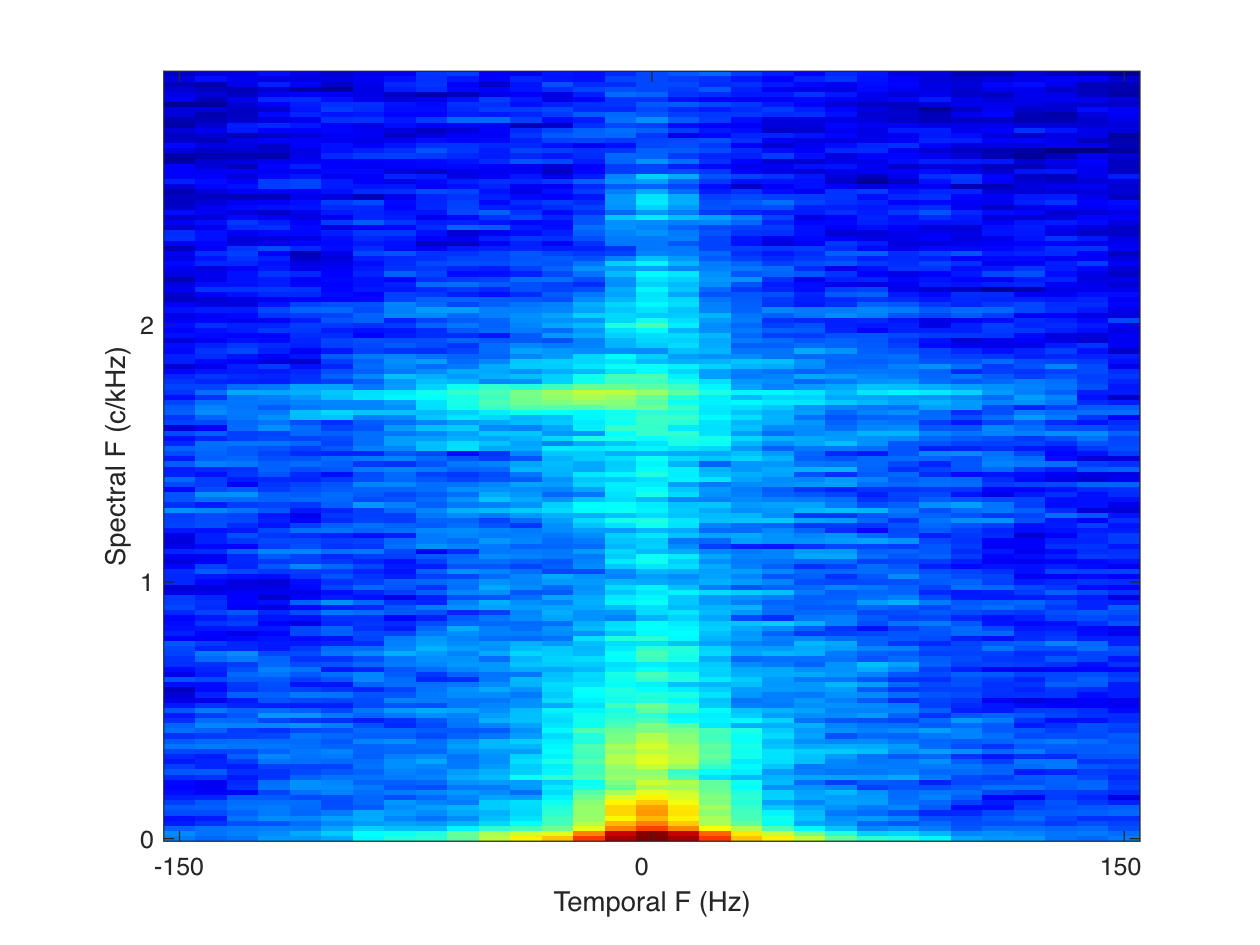

figure()
[CLim1,Im1,~]=plot_mps(BioSoundCall{1,1}.mps_elmts{2}, BioSoundCall{1,1}.wf_elmts{2}, BioSoundCall{1,1}.wt_elmts{2}, 60, nan, 1, [0 3],[-150 150]);
ylabel('Spectral F (c/kHz)')
xlabel('Temporal F (Hz)')

Plot the microphone spectrogram

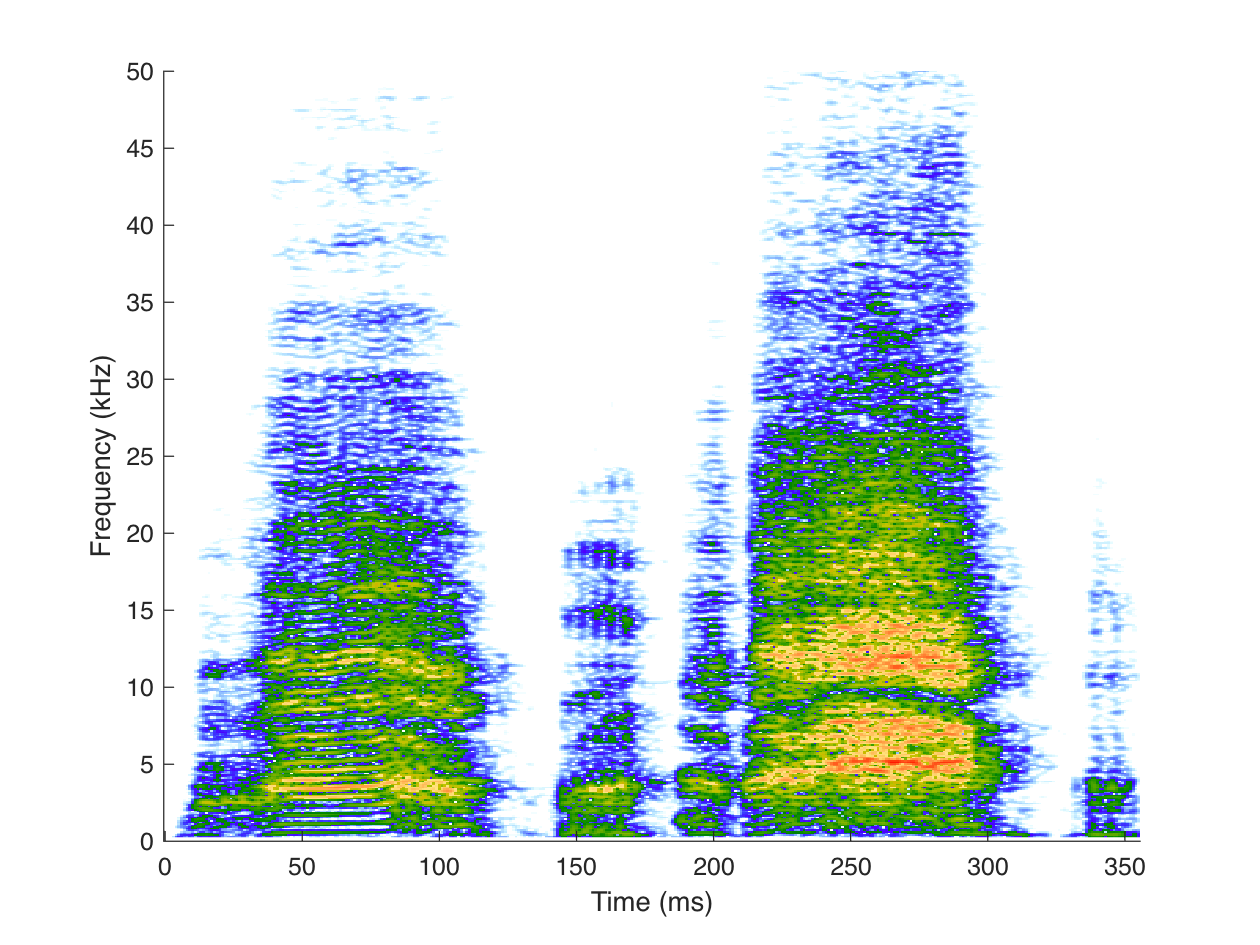

DBNOISE=60;
F=figure();
logB = BioSoundCall{1,1}.spectro_elmts{2};
maxB = max(max(logB));
minB = maxB-DBNOISE;
To = 1:size(BioSoundCall{1,1}.spectro_elmts{2},1);
IM=imagesc(BioSoundCall{1,1}.to_elmts{2}*10^3,BioSoundCall{1,1}.fo_elmts{2}/10^3,logB);          % to is in seconds
axis xy;
caxis('manual');
caxis([minB maxB]);
cmap = spec_cmap();
colormap(IM.Parent, cmap);
v_axis = axis;
v_axis(3)=0;
v_axis(4)=50;
axis(v_axis);
ylabel('Frequency (kHz)')
xlabel('Time (ms)')
box off

function [CLim,Im,MPS4plot, Wt_local, Wf_local]=plot_mps(MPS, Wf, Wt, DBNOISE,CLim,Log, YLim, XLim, TwoDfilter)
%[CB,Im,MPS4plot, Wt_local, Wf_local]=plot_mps(MPS, Wf, Wt, DBNOISE,CLim,Log, YLim, XLim, TwoDfilter)
if nargin<4
    DBNOISE=60;
end

if nargin<6
    Log=1;
end

if nargin<7
    YLim = [0 max(Wf*10^3)];
end
if nargin<8
    XLim = [min(Wt) max(Wt)];
end
if nargin<5
    CLim = nan;
end
if nargin<9
    TwoDfilter=0;
end

Wf_i = logical((Wf*10^3>=YLim(1)).* (Wf*10^3<=YLim(2)));
Wt_i = logical((Wt>=XLim(1)).* (Wt<=XLim(2)));
MPS = MPS(Wf_i, Wt_i);
Wf_local = Wf(Wf_i);
Wt_local = Wt(Wt_i);
if Log
    MPS4plot = 10*log10(MPS);
else
    MPS4plot = MPS;
end
MaxMPS = max(max(MPS4plot));
MinMPS = MaxMPS-DBNOISE;
MPS4plot(MPS4plot < MinMPS) = MinMPS;

if TwoDfilter
    MPS4plot = imgaussfilt(MPS4plot,TwoDfilter);
end

%             imagesc(LogMPS, interpolation='nearest', aspect='auto', origin='lower', cmap=cmap, extent=ex)
Im = imagesc(MPS4plot);
axis xy
colormap(Im.Parent,'jet');
% CB=colorbar();
%     CB.YTick=0;
%     CB.YTickLabel=0;
%     CB.Units = 'inches';
%     CB.Location='north';
%     CB.Position(4) = 0.1;
%     CB.Position(2) = CB.Position(2) + 0.2;
% CB.Label.String = 'Power (dB)';
xlabel('Temporal Frequency (Hz)')
ylabel('Spectral Frequency (Cycles/kHz)')
% get nice X and y tick labels
MaxWf = max(floor(Wf_local*10^3));
YTickLabel=0:MaxWf;
YTick = nan(length(YTickLabel),1);
for yy=1:length(YTick)
    YTick(yy) = find(floor(Wf_local*10^3)==YTickLabel(yy),1);
end
set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
MaxWt = max(ceil(Wt_local*10^-1))*10^1;
XTickLabel = [-MaxWt 0 MaxWt];
XTick = nan(length(XTickLabel),1);
for xx=1:length(XTick)
    [~,XTick(xx)] = min(abs(round(Wt_local)-XTickLabel(xx)));
end
set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
if ~isnan(CLim)
    PlotMPS = gca;
    PlotMPS.CLim = CLim;
else
    PlotMPS = gca;
    CLim = PlotMPS.CLim;
end
end

function [MPS4plot, Wt_local, Wf_local]=plot_mps_original(MPS, Wf, Wt, DBNOISE,CLim,Log, YLim, XLim, TwoDfilter)
if nargin<4
    DBNOISE=60;
end

if nargin<6
    Log=1;
end

if nargin<7
    YLim = [0 max(Wf*10^3)];
end
if nargin<8
    XLim = [min(Wt) max(Wt)];
end
if nargin<5
    CLim = nan;
end
if nargin<9
    TwoDfilter=0;
end

Wf_i = logical((Wf*10^3>=YLim(1)).* (Wf*10^3<=YLim(2)));
Wt_i = logical((Wt>=XLim(1)).* (Wt<=XLim(2)));
MPS = MPS(Wf_i, Wt_i);
Wf_local = Wf(Wf_i);
Wt_local = Wt(Wt_i);
if Log
    MPS4plot = 10*log10(MPS);
    MaxMPS = max(max(MPS4plot));
    MinMPS = MaxMPS-DBNOISE;
    MPS4plot(MPS4plot < MinMPS) = MinMPS;
else
    MPS4plot = MPS;
end

if TwoDfilter
    MPS4plot = imgaussfilt(MPS4plot,TwoDfilter);
end

%             imagesc(LogMPS, interpolation='nearest', aspect='auto', origin='lower', cmap=cmap, extent=ex)
Im = imagesc(MPS4plot);
axis xy
colormap(Im.Parent,'jet');
c=colorbar();
c.Label.String = 'Power (dB)';
xlabel('Temporal Frequency (Hz)')
ylabel('Spectral Frequency (Cycles/kHz)')
% get nice X and y tick labels
MaxWf = max(floor(Wf_local*10^3));
YTickLabel=0:MaxWf;
YTick = nan(length(YTickLabel),1);
for yy=1:length(YTick)
    YTick(yy) = find(floor(Wf_local*10^3)==YTickLabel(yy),1);
end
set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
MaxWt = max(floor(Wt_local*10^-2))*10^2;
XTickLabel = -MaxWt:100:MaxWt;
XTick = nan(length(XTickLabel),1);
for xx=1:length(XTick)
    [~,XTick(xx)] = min(abs(round(Wt_local)-XTickLabel(xx)));
end
set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
if ~isnan(CLim)
    PlotMPS = gca;
    PlotMPS.CLim = CLim;
end
end